% Data import and categorization.
A=[80.197118070747166 -2.5666179827034052;
   96.100337557063114 -2.1269840916834286;
   102.21639050420207 -2.0418362601495867;
   115.87643421262707 -0.94927120819026278;
   111.29692037645944 -0.77116852214250153;
   111.32114732562169 -0.34786388198669016;
   112.83671847665971 -0.33817756808106303;
   101.68168180066911 -0.20539821841875217;
   104.7307892624973 -0.032731705194564142;
   92.051470144509921 0.1114712065857093;
   98.491434194738844 0.1688739978265108;
   84.04461874361705 0.45700722714542374;
   78.979113046489246 0.66221765079119921;
   87.439952721792793 0.70735546499701485;
   76.6596801766987 0.86590277556244155;
   64.227153112762878 1.4006804918975106;
   69.083374826334875 1.8572113116852353;
   67.716633413807259 2.1808909548484241;
   65.407652636407008 2.2720241040189979;
   88.850432917584953 2.7235225355912824;
   81.8739626287759 2.7258357341468651;
   132.05654439038884 3.3487347327508363;
   157.94216153772052 3.7074651941943113;
   193.04399353361654 3.9203050111333511;
   198.94506275634302 3.9481710246716464];
y=A(:,1);
x=A(:,2);


B = [78.979113046489246 0.66221765079119921;
   87.439952721792793 0.70735546499701485;
   76.6596801766987 0.86590277556244155;
   64.227153112762878 1.4006804918975106;
   69.083374826334875 1.8572113116852353;
   67.716633413807259 2.1808909548484241;
   65.407652636407008 2.2720241040189979;
   88.850432917584953 2.7235225355912824;
   81.8739626287759 2.7258357341468651;
   132.05654439038884 3.3487347327508363;
   157.94216153772052 3.7074651941943113;
   193.04399353361654 3.9203050111333511;
   198.94506275634302 3.9481710246716464];
y_1 = B(:,1);
x_1 = B(:,2);

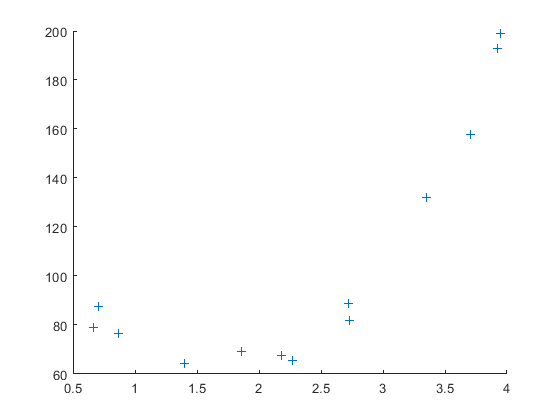

% Considering x > 0.5 only. 
corr(x_1, y_1);
scatter(x_1, y_1, '+');

% regr_1 = regstats(y_1, x_1, 'linear', 'all');
% regr_1.beta;
% regr_1.rsquare;

x12 = x_1.*x_1;
regr_2 = regstats(y_1, [x_1, x12], 'linear', 'all');
regr_2.beta

ans =   131.9905
  -86.3214
   25.7870


regr_2.rsquare

ans = 0.9890

x2 = x.*x;
x3 = x.*x.*x;
regr_3 = regstats(y, [x, x2, x3], 'linear', 'all');
regr_3.beta

ans =    99.3174
  -26.3104
   -3.3668
    4.1070


regr_3.rsquare

ans = 0.9872

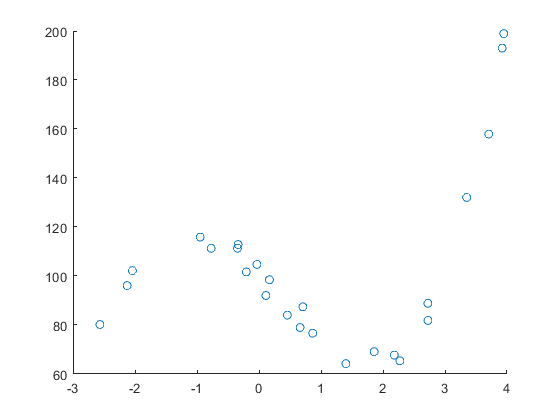

scatter(x, y)

beta_for_poly = flip(regr_3.beta);
p = beta_for_poly

p =     4.1070
   -3.3668
  -26.3104
   99.3174


q = polyder(p)

q =    12.3209   -6.7335  -26.3104


r = roots(q)

r =     1.7599
   -1.2134


X = [];

X(:, 1) = ones(25,1);
X(:, 2) = x;
X(:, 3) = x2;
X(:, 4) = x3;

X;

u = [1 1.7599 1.7599^2 1.7599^3]';
u_2 = [1 (-1.2134) (-1.2134)^2 (-1.2134)^3]';
beta_hat = regr_3.beta;
SSE = regr_3.fstat.sse

SSE = 386.2113

S   = sqrt(SSE/(25-3-1))

S = 4.2885

t = 2.08;
lowerBound_1 = u'*beta_hat - S*t*sqrt(u'*inv(X'*X)*u+1)

lowerBound_1 = 55.4881

upperBound_1 = u'*beta_hat + S*t*sqrt(u'*inv(X'*X)*u+1)

upperBound_1 = 74.4568


lowerBound_2 = u_2'*beta_hat - S*t*sqrt(u_2'*inv(X'*X)*u_2+1)

lowerBound_2 = 109.4328

upperBound_2 = u_2'*beta_hat + S*t*sqrt(u_2'*inv(X'*X)*u_2+1)

upperBound_2 = 128.4635